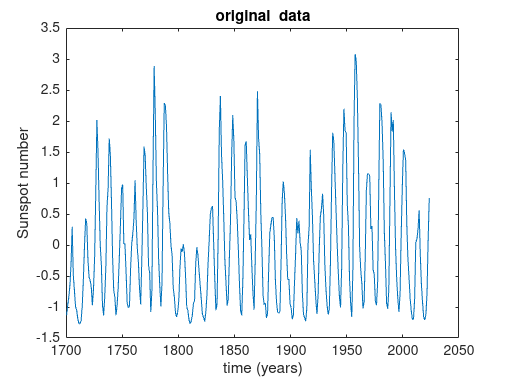

clc; close all; clear global; clear all;

data=readtable('/MATLAB Drive/SWTP/ssn.txt'); %address

data=table2array(data); % conversion to  numeric matrix

time = data(:,1);

ssn=data(:,2); 

m = mean(ssn); sd =std(ssn);

ssn = (ssn-m)/sd;

figure()

plot(time,ssn);

xlabel('time (years)');

ylabel('Sunspot number');

title('original  data');

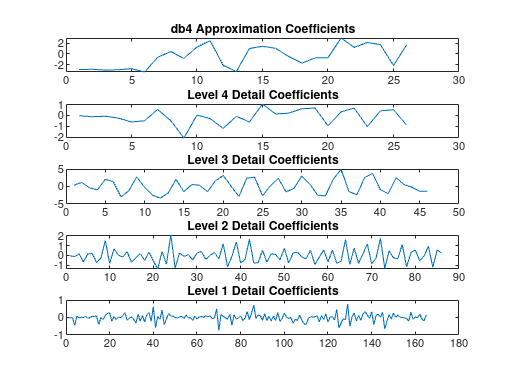

[c,l] = wavedec(ssn,4,'db4'); 				% level 4 decomposition

approx = appcoef(c,l,'db4'); 				% approximation coefficients

[cd1,cd2,cd3,cd4] = detcoef(c,l,[1 2 3 4]); 	% detailed coefficients


%coefficients plot
figure()
subplot(5,1,1)
plot(approx)
title('db4 Approximation Coefficients','linewidth' ,1.5)

subplot(5,1,2)
plot(cd4)
title('Level 4 Detail Coefficients','linewidth' ,1.5)

subplot(5,1,3)
plot(cd3)
title('Level 3 Detail Coefficients','linewidth' ,1.5)

subplot(5,1,4)
plot(cd2)
title('Level 2 Detail Coefficients','linewidth' ,1.5)

subplot(5,1,5)
plot(cd1)
title('Level 1 Detail Coefficients','linewidth' ,1.5)

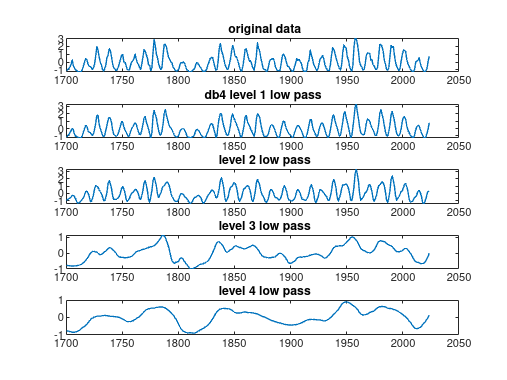


% low pass and high pass filtered signal after reconstruction of db4 coefficients

for i =1:5

level=i;

[c,l]=wavedec(ssn,level,'db4'); %wavelet decomposition

lp=wrcoef('a',c,l,'db4', level); %reconstruction of average (low-pass) coefficient

low_pass(:,i)=lp;

hp1=ssn-lp; %reconstruction of high pass filtered data (fluctuations)

high_pass(:,i)=(hp1);

end


figure() %low pass filtered data plot
subplot(5,1,1)
plot(time,ssn,'linewidth',1)
title(' original data')

subplot(5,1,2)
plot(time,low_pass(:,1),'linewidth' ,1)
title('db4 level 1 low pass')

subplot(5,1,3)
plot(time,low_pass(:,2),'linewidth' ,1)
title(' level 2 low pass')

subplot(5,1,4)
plot(time,low_pass(:,3),'linewidth' ,1)
title(' level 3 low pass')

subplot(5,1,5)
plot(time,low_pass(:,4),'linewidth' ,1)
title(' level 4 low pass')

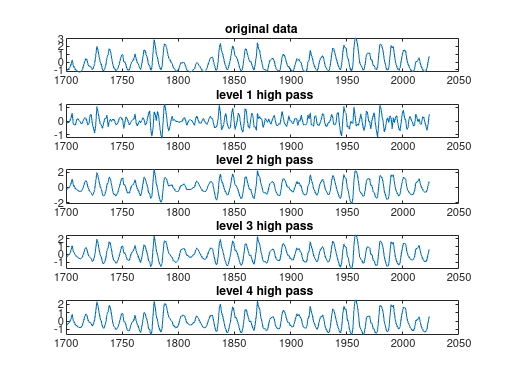

figure() %fluctuation plot

subplot(5,1,1)
plot(time,ssn(:,1))
title('original data ','linewidth' ,1.5)

subplot(5,1,2)
plot(time,high_pass(:,2))
title(' level 1 high pass','linewidth' ,1.5)

subplot(5,1,3)
plot(time,high_pass(:,3))
title(' level 2 high pass','linewidth' ,1.5)

subplot(5,1,4)
plot(time,high_pass(:,4))
title(' level 3 high pass','linewidth' ,1.5)

subplot(5,1,5)
plot(time,high_pass(:,5))
title(' level 4 high pass','linewidth' ,1.5)

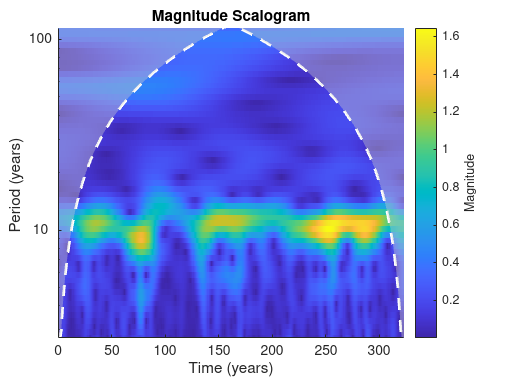

%continuous wavelet
figure()
cwt(ssn, "amor", years(1)); 

[WT,F,COI] =cwt(ssn, "amor", years(1));

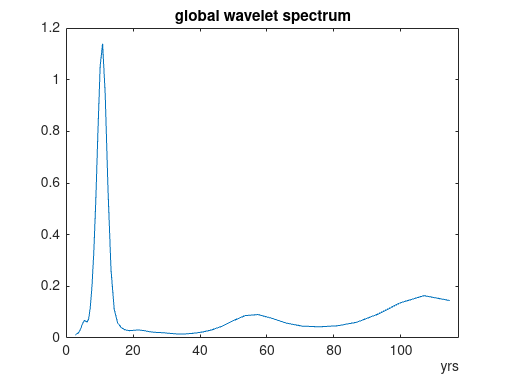

%global wavelet spectrum

WT_norm = WT.*conj(WT);
WT_norm_avg = mean(WT_norm,2);
plot(F, WT_norm_avg);
title('global wavelet spectrum','linewidth' ,1.5);